# Range Field

This widget combines multiple numeric edit fields that form elements of a 1-dimensional array. It is intended for small arrays typically 2 to 5 values. Optionally you may impose restrictions on the numerical range. You can also force the array to be `increasing` or `decreasing`. You can also set orientation as `horizontal` or `vertical`.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 250 50]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

rfWidget = wt.RangeField(gridObj);
rfWidget.ValueChangedFcn = @(src,evt)disp(evt);
rfWidget.Value = [100 500];

Optionally, place some restrictions:

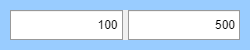

rfWidget =   RangeField with properties:

                  Value: [100 500]
                 Limits: [0 Inf]
    LowerLimitInclusive: off
    UpperLimitInclusive: on
        ValueChangedFcn: @(src,evt)disp(evt)
               Position: [11 11 230 30]

  Show all properties


rfWidget.Tooltip = "Enter the range of positive values to use (must be > 0).";
rfWidget.LowerLimitInclusive = false;
rfWidget.UpperLimitInclusive = true;
rfWidget.Limits = [0, inf]

*Copyright 2024-2025 The MathWorks, Inc.*